# Calculate the Length to Height Ratio of a Flatfish

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

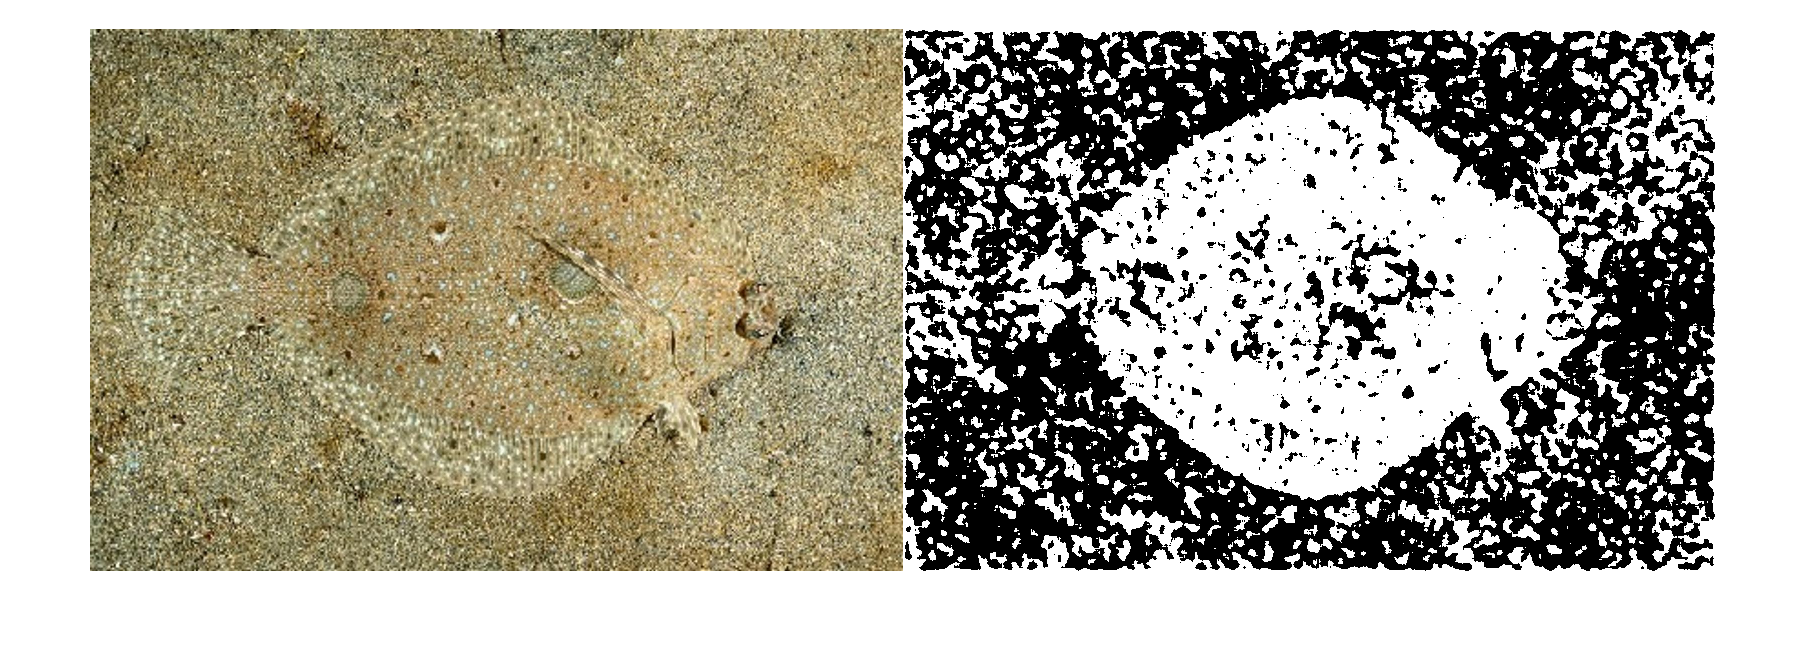

flatFish = imread("./images/flatfish.jpg");

% Create mask with local function at bottom of script
fishBW = fishMask(flatFish);     
imshowpair(flatFish, fishBW, "montage")

## Task 1

You only need to work with the connected component representing the fish, which is the largest one.  

You can use the `bwpropfilt` function to keep the `n` largest or smallest objects when sorted by `attrib`.

`BW2` `=` `bwpropfilt``(``BW``,``attrib``,``n``,``keep``)``;`

Specify `keep` as either `"largest"` or `"smallest"`.

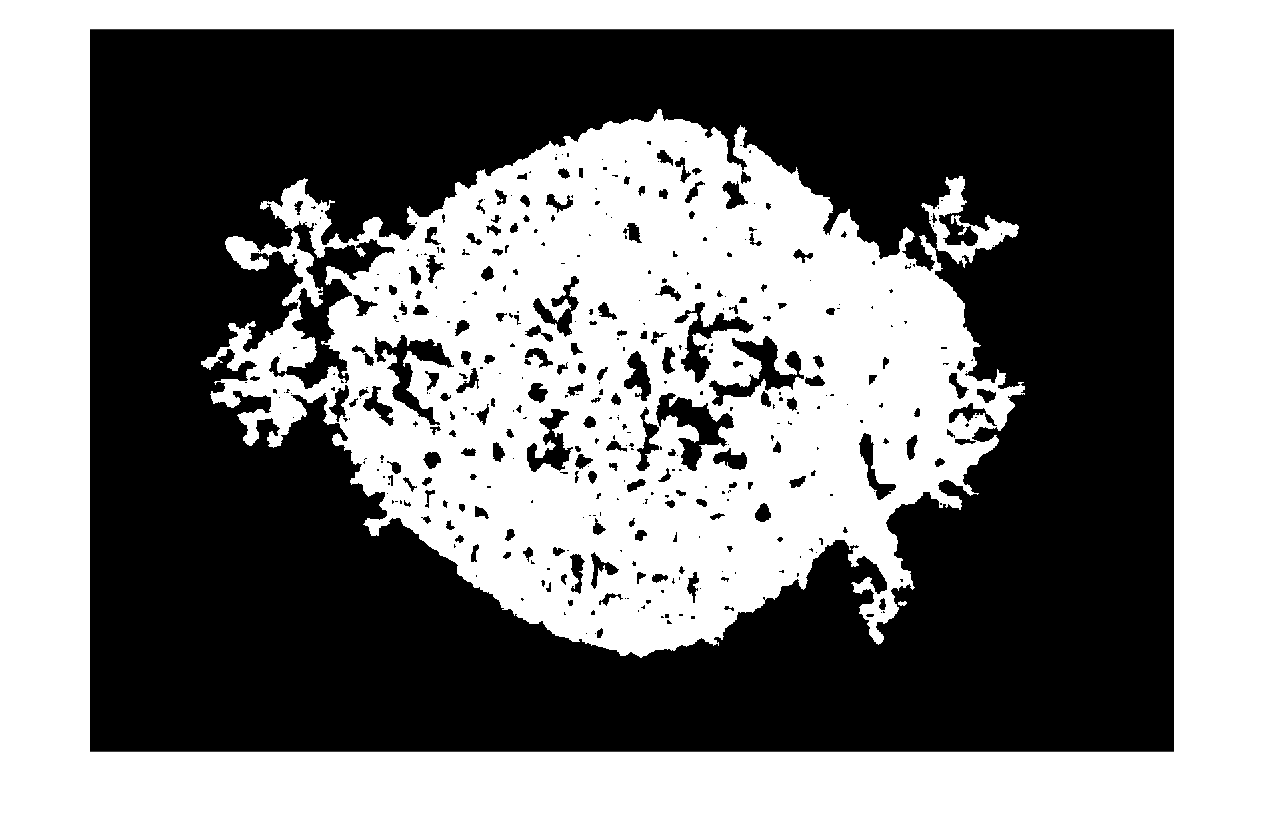

fishOnly = bwpropfilt(fishBW, "Area", 1, "largest");
imshow(fishOnly)

## Task 2

The `regionprops` function works on binary images as well as on label matrices. The syntax is the same.

`stats` `=` `regionprops``(``output``,``BW``,``props``)`

`output` specifies the type of `stats` and is either `"struct"` or `"table"`.  `BW` is a binary image, and `props` is a string array specifying the properties to return. 

fishOrient = regionprops("table", fishOnly, "Orientation")

fishOrient = table
    Orientation
    ___________

      -4.0427  


## Task 3

You can use `imrotate` to rotate an image counterclockwise.

`I2` `=` `imrotate``(``I``,``angle``)``;`

angle = fishOrient.Orientation;
fishRot = imrotate(flatFish, -angle);

## Task 4

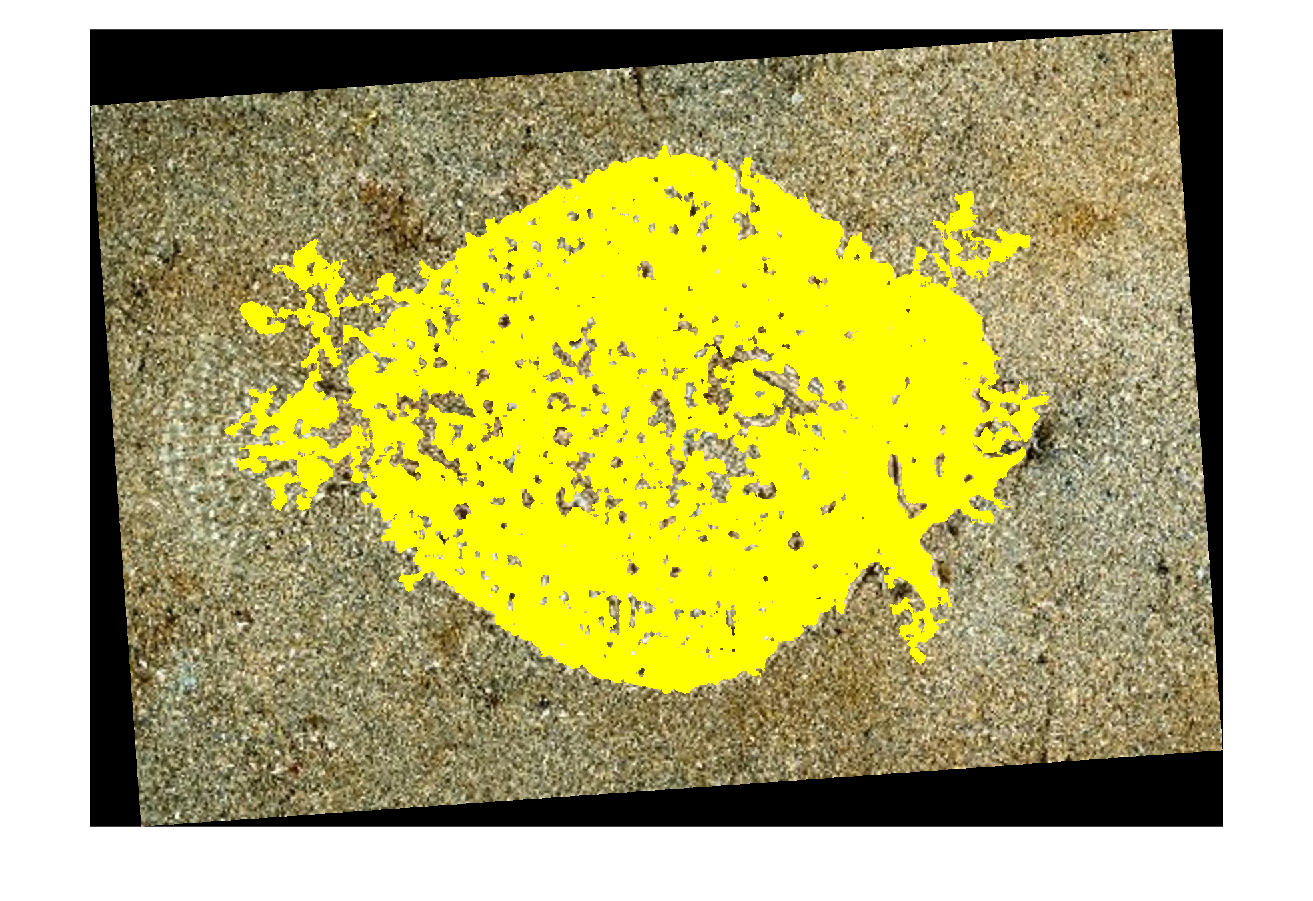

BWrot = imrotate(fishOnly, -angle);
rotOverlay = imoverlay(fishRot, BWrot);
imshow(rotOverlay)

## Task 5

fishBB = regionprops("table", BWrot, "BoundingBox")

fishBB = table
              BoundingBox           
    ________________________________

    201.5    174.5     1237      823


fishBox = fishBB.BoundingBox

fishBox = 1.0e+03 *

    0.2015    0.1745    1.2370    0.8230


## Task 6

You can display a bounding box over an image by passing it as the position to the `rectangle` function.

`hold` `on`

`rectangle``(``"Position"``,``pos``,``"Name"``,``Value``)`

`hold` `off`

`pos` is the position of the rectangle. With name-value pairs, you can specify properties of the rectangle like `"EdgeColor"` and `"LineWidth"`.

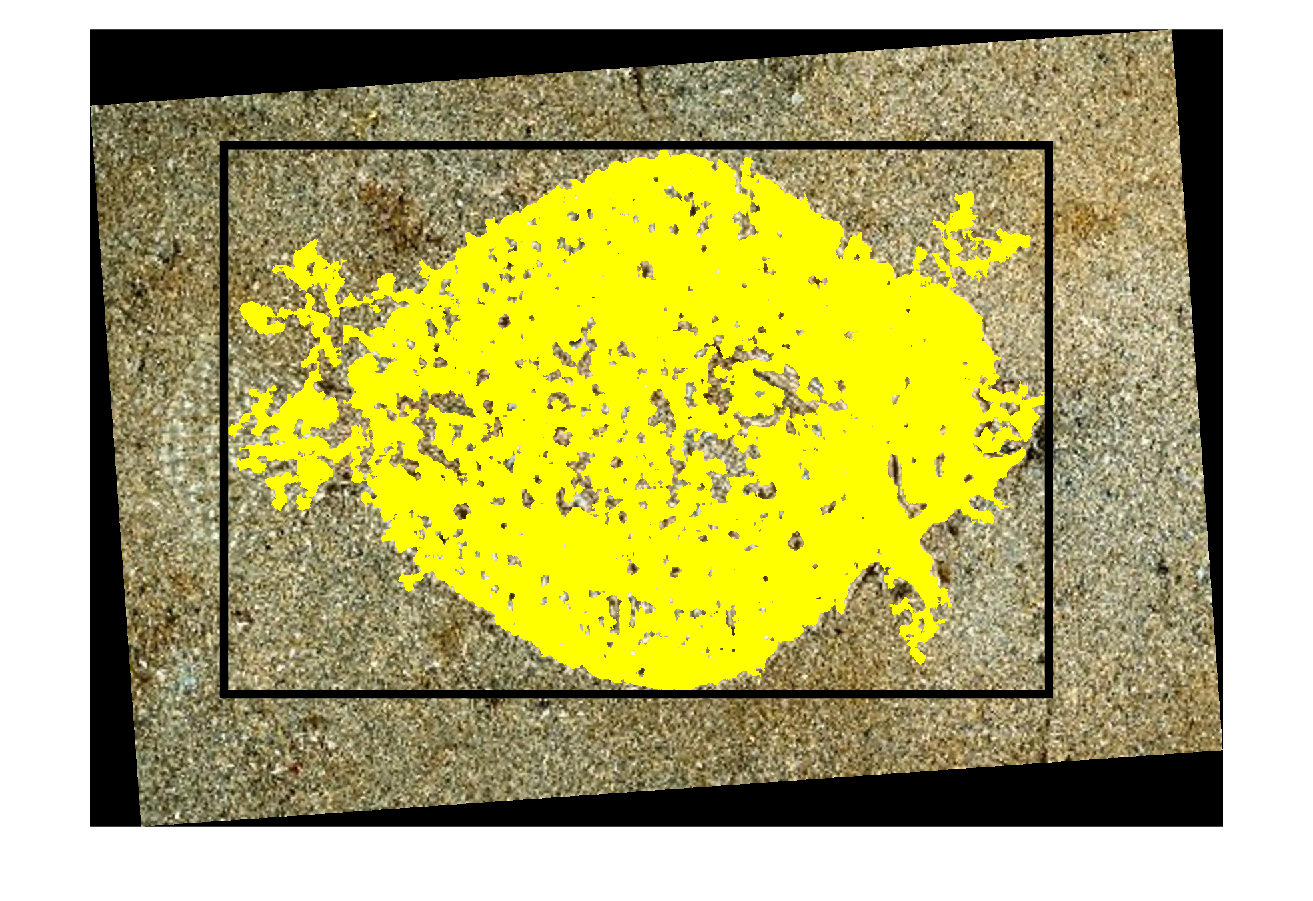

hold on
rectangle("Position", fishBox, "LineWidth", 5)
hold off

## Task 7

The bounding box is a 4-element vector, `[x y w h]` where `x` and `y` are the coordinates of the bottom left corner of the box and `w` and `h` are the width and height of the box.

wt = fishBox(3);
ht = fishBox(4);

ratio = wt / ht

ratio = 1.5030

function fishBW = fishMask(flatFish)
    % use texture segmentation and smoothing 
    % to segment camouflaged fish
    
    fishGray = rgb2gray(flatFish);
    fishSTD = stdfilt(fishGray);
    fishSTD = rescale(fishSTD);
    
    filterSize = [15 15];
    fishFilt = medfilt2(fishSTD, filterSize);
    
    fishBW = ~imbinarize(fishFilt);
end